% This is for Task 9
% This creates the filename for us to load the reviews
% of Our Deep learning model.
filename_forDL = "JewelleryReviewsDeepLearning.csv";

% This reads the deeplearning data into a table. 
DeepLearningTable_start = readtable("JewelleryReviewsDeepLearning.csv",'TextType','string');

%This sets the random seed to be 42 to en sure reproducability
rng(42);

% Because the reviews are in order in the initial table, they need to be
% shuffled to ensure randomness and accurate training. 
DeepLearningTable_shuffled = DeepLearningTable_start(randperm(size(DeepLearningTable_start,1)), :);


% Converting the labels to categorical
DeepLearningTable_shuffled.Ratings = categorical(DeepLearningTable_shuffled.Ratings);


% This creates a bag of words out of our preprocessed training documents.
% It also creates a random bag as we need for the self defined function
textData = DeepLearningTable_shuffled.Reviews;
randombag = bagOfWords(tokenizedDocument(textData));
textData = preprocessText(textData,randombag);

terms_2 = 19300

number_of_terms_removed_by2 = 0

terms_3 = 19101

number_of_terms_removed_by3 = 199

terms_4 = 18710

number_of_terms_removed_by_4 = 391

terms_5 = 13418

number_of_terms_removed_by5 = 5292

terms_6 = 13039

number_of_terms_removed_by6 = 379

terms_7 = 12708

number_of_terms_removed_by7 = 331

terms_8 = 12575

number_of_terms_removed_by8 = 133

bag_for_DL = bagOfWords(textData);

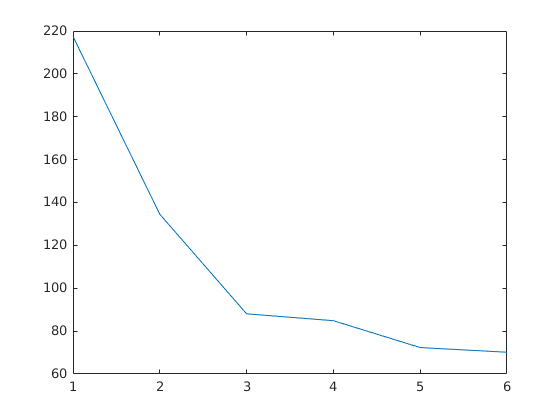

% This part plots the singular values to obtain the best number of
% components for the LSA model. 

singular_values = svds(bag_for_DL.Counts);
plot(sparse(singular_values))



% This creates the LSA model using the bag from training documents
% This model contains the matrices  we need to use. I use 3 components
% after analyzing the elbow curve
deep_learning_LSA = fitlsa(bag_for_DL,3);



% THis creates an empty cell array to satisfy the datatype requirements for
% the LSTM model
docScore = {}


docScore =

  0×0 empty cell array




% This loop is the most important part of the task. This uses the document
% scores associated with the LSA model defined above. It saves each row of
% the DocumentScores and adds it to the correspondig index of the docScore
% cell array. This means that the docScore cell array is N x1 where N is
% the number of documents. THe value at the i'th index of docScore is a
% sequance vector representing the i'th document. This ensures the LSTM is
% able to use the reduced dimensionality of the review documents. 
for i=1:12000
    docScore{i} = deep_learning_LSA.DocumentScores(i,:);
end

% This splits data into the training and testing.10% is used as testing
textDataTraining = docScore(1:10800);
trainingY = DeepLearningTable_shuffled.Ratings(1:10800);
textDataTest = docScore(10801:end);
testY = DeepLearningTable_shuffled.Ratings(10801:end);

% This splits training into training and validating sets.10% is used as
% validation 
TrainX = textDataTraining(1:9600);
TrainX_Transposed = TrainX';
trainY = trainingY(1:9600);
ValidateX = textDataTraining(9601:end);
ValidateY = trainingY(9601:end);


% Create and Train LSTM Network using the train and val sets from above
% This part is nearly identical to the tutorial. however, it is important 
inputSize = 1;
embeddingDimension = 50;
numHiddenUnits = 80;
numWords = length(deep_learning_LSA.Vocabulary);
numClasses = numel(categories(trainY));
layers = [ ...
    sequenceInputLayer(inputSize)
    wordEmbeddingLayer(embeddingDimension,numWords)
    lstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer]

layers =   7x1 Layer array with layers:

     1   ''   Sequence Input          Sequence input with 1 dimensions
     2   ''   Word Embedding Layer    Word embedding layer with 50 dimensions and 12575 unique words
     3   ''   LSTM                    LSTM with 80 hidden units
     4   ''   Fully Connected         5 fully connected layer
     5   ''   Fully Connected         5 fully connected layer
     6   ''   Softmax                 softmax
     7   ''   Classification Output   crossentropyex


% Specify Training Options
%https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html
options = trainingOptions('adam', ...
    'MiniBatchSize',16, ...
    'GradientThreshold',2, ...
    'LearnRateDropFactor',0.2, ...
    'LearnRateDropPeriod',5, ...
    'ValidationData',{ValidateX,ValidateY}, ...
    'Plots','training-progress',...
    'Verbose',false)

options =   TrainingOptionsADAM with properties:

           GradientDecayFactor: 0.9000
    SquaredGradientDecayFactor: 0.9990
                       Epsilon: 1.0000e-08
              InitialLearnRate: 1.0000e-03
             LearnRateSchedule: 'none'
           LearnRateDropFactor: 0.2000
           LearnRateDropPeriod: 5
              L2Regularization: 1.0000e-04
       GradientThresholdMethod: 'l2norm'
             GradientThreshold: 2
                     MaxEpochs: 30
                 MiniBatchSize: 16
                       Verbose: 0
              VerboseFrequency: 50
                ValidationData: {{1×1200 cell}  [1200×1 categorical]}
           ValidationFrequency: 50
            ValidationPatience: Inf
                       Shuffle: 'once'
                CheckpointPath: ''
          ExecutionEnvironment: 'auto'
                    WorkerLoad: []
                     OutputFcn: []
        

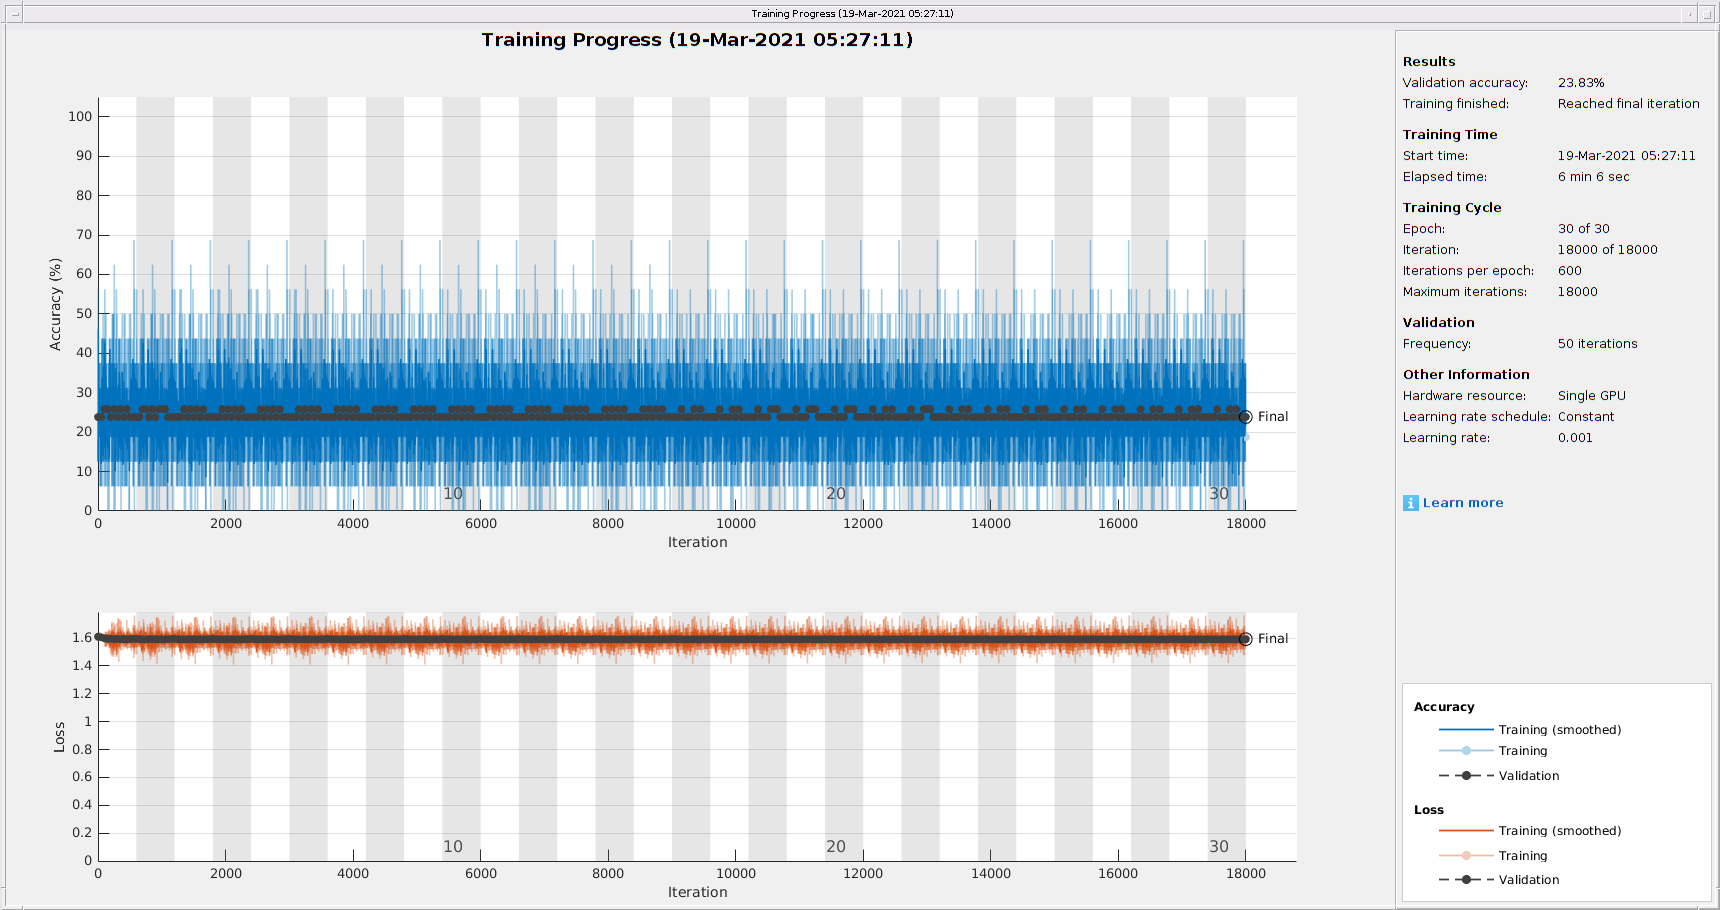


net = trainNetwork(TrainX_Transposed,trainY,layers,options);

savefig("LSTMwithLSA.fig")

% This tests the above defined model on the training and testing set.
% Done in a similar manner to the tutorial. This also shows the confusion
% matrix

%use the pretrained model to predict 
PredictResults = classify(net,textDataTest);
% This access the reviews as text for displaying results
TestingReviews = DeepLearningTable_shuffled.Reviews(10801:end);
% Check Result
TestNum = length(textDataTest);
correctNum = 0;

for i=1:TestNum
    % Displaying some results just for visualization. 
    if i<=20
        sprintf('Review: %s\nPredicted Result: %s\nLabel Rating: %s', TestingReviews(i),PredictResults(i),testY(i))
    end
   % Acuracy calculation
    if PredictResults(i)==testY(i)
        correctNum = correctNum + 1;
    end
end

ans =     'Review: In a word - BIG! My wife wanted some fun earrings to wear to work - she manages the cheese section of an upscale deli/market. I did not realize how large the foam cheese earrings were, but she liked them anyway.
     
     Predicted Result: 4
     Label Rating: 4'


ans =     'Review: Less than three months later, the cz diamonds started falling out, starting with the biggest one. Very sad now :(
     
     Predicted Result: 4
     Label Rating: 2'


ans =     'Review: I bought this bracelet for my wife for Christmas. It arrived promptly and in good shape. It was however the wrong size. I have tried numerous times to contact the company for an exchange and have not recieved one reply. I will not purchace anything from them again.
     
     Predicted Result: 4
     Label Rating: 3'


ans =     'Review: It's way smaller than I expected. Beautiful color though. Taller ladies should be aware of the size of this pair of earrings.
     
     Predicted Result: 4
     Label Rating: 3'


ans =     'Review: The earrings are very nice, they have long post which is good for me because i have big earlobes.Fast shipping tooThe only thing i dont like is the box, its very cheap box and not sturdy. When it came in the mail the box was squished.
     
     Predicted Result: 4
     Label Rating: 4'


ans =     'Review: I found these earrings and fell in love with them. They are my birthstone and it is very hard for me to find earrings that I like with my birthstone in them. I was very excited to find them and a ring to match.
     
     Predicted Result: 4
     Label Rating: 5'


ans =     'Review: I loved this ring when I first saw it online and admired it for some time. Unfortunately, it was much smaller than it looked online and I was really hoping for a larger, statement type ring. I ended up having to return the ring since it didn't really stand out as I had hoped. If you however, like a smaller, more petite look, the ring is definitely very pretty. The color of the stone was very nice, clear and vibrant. I just needed something to really stand out in size and sadly this wasn't it.
     
     Predicted Result: 4
     Label Rating: 3'


ans =     'Review: great basic string of pearls, wonderful price.The pearls have a strong greenish-blue cast, which is pretty.
     
     Predicted Result: 4
     Label Rating: 4'


ans =     'Review: they were cute enough when I got them. great for casual wear with jeans. they broke in a little over a week. seems to be the re-occuring theme with anything from silverspeck. I have begun avoiding any jewelry they sell on here.
     
     Predicted Result: 4
     Label Rating: 2'


ans =     'Review: I thought this thing would just BLING out of the box but it did not. I asked my wife what she thought of it and she just said it was good. That means to me it's not the cats meow. It is very small and again doesn't really sparkle.
     
     Predicted Result: 4
     Label Rating: 3'


ans =     'Review: These are free in Turkey when you buy silver. Lost mine. They work great, but shipping was high for a one OZ item.
     
     Predicted Result: 4
     Label Rating: 3'


ans =     'Review: This is supposed to be a nickel free ring. I'm pregnant so I needed a bigger wedding ring for my pregnant fingers and didn't want to spend a ton. This worked last pregnancy with another ring that I wore for months without issue until it broke (another "cheapy" ring). Anyway, I was worried about having a reaction since my skin is sensitive and was excited that the ring said nickel free.I've worn it for 2 days and couldn't wear it any more because of the itchy rash it left under where the ring touched my finger. Maybe it doesn't have nickel, but it's definitely not hypoallergenic. I realize that it wasn't advertised as such but buyer beware if you are looking for a ring to be gentle to your sensitive skin.I will also second the ill fitting of the pair. The two rings never fit together correctly and constantly have to be moved into place. I was actually pretty disappointed with how the ring looked in person. The large CZ was nice but the detailing on the sides looks pre

ans =     'Review: This actually looks real nice on the website. I ordered it for my wife last Christmas. When I received it, I was dissapointed at its quality. It wasn't worth the shipping charge (free). I decided to give it to my girlfriend instead.
     
     Predicted Result: 4
     Label Rating: 1'


ans =     'Review: i feel the pic online is pretty nice, so i placed the order. but when i got it this morning, i was so disappointed that it looks so harsh even not wearing it. You can tell it's not in fine quality, maybe that's for its low price, but the main thing is this ring is not good for you if your finger is relative thin. And it's not that expensive, makes me not willing to return it, kinda waste of money.
     
     Predicted Result: 4
     Label Rating: 1'


ans =     'Review: Bracelet does not look like picture. The picture makes the bracelet look as if it is a smooth silver surface, but when the bracelet came it was not smooth, it was lumpy. Also, very flimsy and felt as if it would be easily bent out of shape. If you are looking for a high quality bracelet this is not it.
     
     Predicted Result: 4
     Label Rating: 2'


ans =     'Review: If the color of this stone is just as pictured on the web, this is NOT a London Blue Topaz, which is a much deeper color and has more value than that of other topaz colors.
     
     Predicted Result: 4
     Label Rating: 1'


ans =     'Review: this ring is so ugly, and huge, but its ok for your daughter on holloween or something if she is going to be a princess or something. i wouldnt wear it in public.
     
     Predicted Result: 4
     Label Rating: 2'


ans =     'Review: Completes my Black & White and X's & O's sets. Had them for a while and wear them often.
     
     Predicted Result: 4
     Label Rating: 4'


ans =     'Review: I got this for a gift for my sister with the healing qualities of amber in mind (use amber teething necklaces for the babes) it was actually a little bigger than i expected and i like the fact it floats around inside the spheres. my sis really liked it, it came with a nice authenticity card and i put it on a chain for her that was bought seperately.
     
     Predicted Result: 4
     Label Rating: 4'


ans =     'Review: This is a lovely pendant whoever it is smaller than I thought it would be. Most of Amazon's jewelry has a size comparison. This one did not and as a result I was a bit disappointed.
     
     Predicted Result: 4
     Label Rating: 3'


TestAccuracy = correctNum/TestNum*100

TestAccuracy = 24.0833


% Create Confusion Matrix

C = confusionmat(testY,PredictResults)

C =      0     0     0   201     0
     0     0     0   195     0
     0     0     0   207     0
     0     0     0   289     0
     0     0     0   308     0


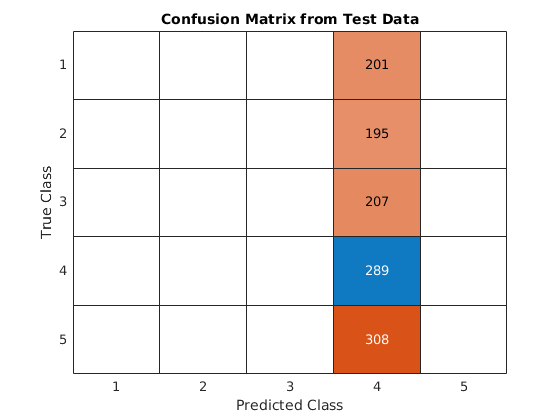

figure
confusionchart(C)
title("Confusion Matrix from Test Data")

% Now classifying the train data to show confusion matrices for validating

%use the pretrained model to predict 
PredictResultsValidation = classify(net,ValidateX);
% This access the reviews as text for displaying results
ValidatingReviews = DeepLearningTable_shuffled.Reviews(9601:10800);
% Check Result
ValidateNum = length(ValidateX);
correctNumValidate = 0;

for i=1:ValidateNum
  % As above section. BUt without all results, results are initially showed
  % just for visualization.
    if PredictResultsValidation(i)==trainY(i)
        correctNumValidate = correctNumValidate + 1;
    end
end
ValidationAccuracy = correctNumValidate/ValidateNum

ValidationAccuracy = 0.2558


% Create Confusion Matrix

CValidate = confusionmat(ValidateY,PredictResultsValidation)

CValidate =      0     0     0   208     0
     0     0     0   206     0
     0     0     0   190     0
     0     0     0   286     0
     0     0     0   310     0


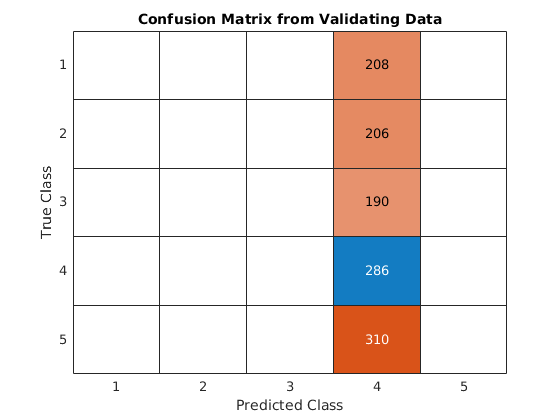

figure
confusionchart(CValidate)
title("Confusion Matrix from Validating Data")

% Now classifying the train data to show confusion matrices for training

%use the pretrained model to predict 
PredictResultsTraining = classify(net,TrainX_Transposed);
% This access the reviews as text for displaying results
TrainingReviews = DeepLearningTable_shuffled.Reviews(1:9600);
% Check Result
TrainNum = length(TrainX_Transposed);
correctNumTrain = 0;

for i=1:TrainNum
   % Getting accuracy
    if PredictResultsTraining(i)==trainY(i)
        correctNumTrain = correctNumTrain + 1;
    end
end
TrainingAccuracy = correctNumTrain/TrainNum

TrainingAccuracy = 0.2526


% Create Confusion Matrix

CTrain = confusionmat(trainY,PredictResultsTraining)

CTrain =            0           0           0        1591           0
           0           0           0        1599           0
           0           0           0        1603           0
           0           0           0        2425           0
           0           0           0        2382           0


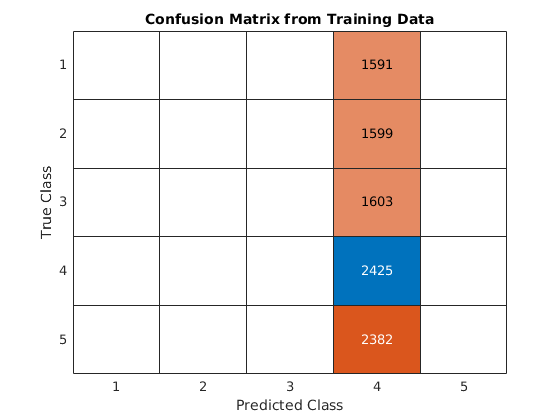

figure
confusionchart(CTrain)
title("Confusion Matrix from Training Data")